## 20250228 demo.m に，位相のオラクル情報を使った差分

残響除去後のスペクトルに，オラクルから得る位相差分を貼り付ける方法を検証する．位相の話がいったん落ち着くので，手法のメインなアイディアの良さを評価できることが期待できる．

clear

settings

% DGT tool
F = DGTtool("windowLength", 512, "windowShift", 128);

% audio data loading
num_piece = 2;
for i=1:num_piece
    audiofilename = "9w3r7y_01_%d";
    [temp, fs] =  audioread("input/" + sprintf(audiofilename,i)+".wav");
    ss{i} = temp(:,1);
end
s = [ss{1}; ss{2}];
num_mic = 1;

% ir data loading
[ir, ~] = audioread("BFTLSPACELIBRARY_ChamberAL_11025.wav");
%[ir, fs] = audioread("logic03sWoodenBooth8000.wav");
%[ir{2}, fs(2)] = audioread("../data/BF TL SPACE LIBRARY/Drumbrella/Drumbrella 5'.R.wav");

Malloc

rt = zeros(1,1); % reverb time in sec
obs = cell(1,num_piece); % obs
X = cell(1, num_piece); % STFTs of obs. signal
S = cell(1, num_piece); % STFTs of dry signal
N = zeros(1, num_piece); % length of obserbation
Lir = zeros(1, 1); % ir length = d + 1
l = zeros(1, num_piece); % length of deconvoluted signal

## resample and shortening

% calcurate the reververation time (RT60)
rt = reverb_time(ir, fs);
ir = ir(1:fs); ir = ir / norm(ir);
IR = F(ir);
Lir = size(IR, 2);

for j = 1:num_piece
    obs{j} = conv(ss{j}, ir);
    X{j} = F(obs{j});
    N(j) = size(X{j}, 2);
    S{j} = F(ss{j});
end
obsCat = [obs{1}; obs{2}];
D = Lir - 1;
padding = -2;
D = D + padding;
Lir = Lir + padding;

## deconvolution in TF domain

malloc

Fq = size(X{1}, 1);
for i = 1:2, l(i) = N(1, i) - Lir(1) + 1; end
RET1 = zeros(Fq, l(1)); RET2 = zeros(Fq, l(2));
RET1W = zeros(Fq, l(1)); RET2W = zeros(Fq, l(2));
RET_slra = zeros(Fq, sum(l));
% ratio of minimum and the 2nd minimum singular value
singValRatio = zeros(Fq, 1);

% frequency-wise 

時間領域で観測 (x) がクリーン信号 (s) とIR (h) の畳み込みで表されているとする:

$\textrm{Time domain:}~{\bf x} = {\bf s} * {\bf h}$.

それらのDGT (X_f, S_f, H_f) に対して，周波数 f のサブバンドで畳み込みが近似的に成り立っているという立場をとる．


$$\textrm{TF domain}~{\bf X}_f \approx {\bf S}_f * {\bf H}_f
$$


今，独立な二つのクリーン信号 s^1, s^2 があって，同一のIRが畳み込まれたものを観測しているとする:

$\textrm{Time domain} : {\bf x}^{1} = {\bf s}^1 * {\bf h}, {\bf x}^2 = {\bf s}^2* {\bf h}$.

TF領域では，それに対応して


$$\textrm{TF domain} : {\bf X}^{1}_f = {\bf S}^1_f * {\bf H}_f, {\bf X}^2_f = {\bf S}^2_f* {\bf H}_f$$


がある．式をいじって，次を得る:

$\textrm{TF domain} : {\bf X}^{1}_f * {\bf S}_f^2 = {\bf X}^2_f * {\bf S}^1_f,= {\bf S}_f^1*{\bf S}^2_f* {\bf H}_f$.

一つ目の等号の部分から


$$\textrm{TF domain} : {\bf X}^{1}_f * {\bf S}_f^2 - {\bf X}^2_f * {\bf S}^1_f = {\bf 0}$$


これを畳み込み行列を使って表すと，


$$\textrm{TF domain} : \\
{\rm Conv}({\bf X}^{1}_f) {\bf S}_f^2 - {\rm Conv}({\bf X}^2_f) {\bf S}^1_f = {\bf 0}\\ \downarrow\\
\left[{\rm Conv}({\bf X}^{2}_f)  ~{\rm Conv}(-{\bf X}^1_f)\right]
\left[\begin{array}{c}{ {\bf S}^1_f \\{\bf S}_f^2\end{array}\right]= {\bf 0}
$$


（最後に出てきた式の係数行列はSylvester行列と名前がついている）


$${\rm Sylvester} \overset{\rm def}{=} \left[{\rm Conv}({\bf X}^{2}_f)  ~{\rm Conv}(-{\bf X}^1_f)\right]$$


Sylvester行列の零空間の基底ベクトルとしてクリーン信号S_f^1, S_f^2 を獲得する．

TF領域での「近似」畳み込みモデルを使っているので，上記のSylvester行列はフルランク行列になってしまっている，

つまり零空間はないのだが，その代わりに最小特異値に対応する右特異ベクトルを使用してクリーン信号の復元を試みる．

parfor f = 1:Fq
    temp = X{1, 1};  X1f = temp(f, :)';
    temp = X{1, 2};  X2f = temp(f, :)';
    Xf = [X1f; X2f];
    XfNorm = norm(Xf);   XfPhase = Xf ./ abs(Xf);

    % Null-space calculation via (not structured) low-rank approximation
    Sylvester = [convmtx(X2f, l(1)) convmtx(-X1f, l(2))];
    [~, Sigma, V] = svd(Sylvester, "econ");
    Sigma = diag(Sigma); singValRatio(f) = Sigma(end) / Sigma(end-1);
    Vf = V(:,end);
    Vf = XfNorm * Vf / norm(Vf); % scale recovery
    VfAng = angle(Vf);

    % % IR estimation
    % A = [convmtx(v1, L(1)); convmtx(v2, L(1))];     b = [X1f; X2f];
    % Hhat = A \ b; % calc. IR (TF domain)
    % HhatPhase = Hhat / abs(Hhat);
    % [Hhatmax, idx_HhatPeak] = max(abs(Hhat));

    % use Oracle Phase info.
    S1f = S{1,1}(f,:); S2f = S{1,2}(f,:);  Sf = [S1f'; S2f'];
    SfAng = angle(Sf);

    % オラクルの位相とのズレが最小となるように回転させる
    aveAngDiff = weightedMeanWithZeroPadding(SfAng, VfAng);
    EstPhaseUsingOracle = exp(1i * aveAngDiff);
    Vf_avephase = Vf * EstPhaseUsingOracle; % / Hhatmax;

    % オラクル振幅を重みとした加重平均で位相を回転させる
    weight = abs(Sf);
    % aveAngDiffW = sum(weight.*(SfAng - VfAng)) / sum(weight);
    aveAngDiffW = weightedMeanWithZeroPadding(SfAng, VfAng, weight);
    EstPhaseUsingOracleW = exp(1i * aveAngDiffW);
    Vf_w = Vf * EstPhaseUsingOracleW;

    v1 = Vf_avephase(1:l(1));
    v2 = Vf_avephase(l(1)+1:end);

    RET1(f,:) = v1';   RET2(f,:) = v2';
    RET1W(f,:) = Vf_w(1:l(1))'; RET2W(f,:) = Vf_w(l(1)+1:end)';
end

ret = cell(1);
ret{1} = F.pinv(RET1);  ret{2} = F.pinv(RET2);

index computed (OLA)


ret_w{1} = F.pinv(RET1W);    ret_w{2} = F.pinv(RET2W);

for i=1:2
    len_ss = length(ss{i});
    len_ret = length(ret{i});
    if len_ss > len_ret
        ss{i} = ss{i}(1:len_ret);
        len_ss = len_ret;
    end
    [SDR,SIR,SAR,perm] = bss_eval_sources(obs{i}(1:len_ss)', ss{i}');
    fprintf("obs: SDR %2.3f, SIR %2.3f, SAR %2.3f\n", SDR, SIR, SAR)

    [SDR,SIR,SAR,perm] = bss_eval_sources(ret{i}(1:len_ss)', ss{i}');
    fprintf("ret: SDR %2.3f, SIR %2.3f, SAR %2.3f\n", SDR, SIR, SAR)

    [SDR,SIR,SAR,perm] = bss_eval_sources(ret_w{i}(1:len_ss)', ss{i}');
    fprintf("ret(w): SDR %2.3f, SIR %2.3f, SAR %2.3f\n", SDR, SIR, SAR)

    audiowrite("output/" + sprintf(audiofilename +"_wet.wav", i), obs{i}, fs)
    audiowrite("output/" + sprintf(audiofilename +"_lra_ORACLE_pad=%d.wav", i, padding), ret{i}, fs)
    audiowrite("output/" + sprintf(audiofilename +"_lra_ORACLE(w)_pad=%d.wav", i, padding), ret_w{i}, fs)
    % audiowrite("output/slra.wav", ret_slra, fs)
end

obs: SDR 0.689, SIR Inf, SAR 0.689


ret: SDR 6.503, SIR Inf, SAR 6.503


ret(w): SDR 6.480, SIR Inf, SAR 6.480


obs: SDR -0.120, SIR Inf, SAR -0.120


ret: SDR 7.118, SIR Inf, SAR 7.118


ret(w): SDR 6.837, SIR Inf, SAR 6.837


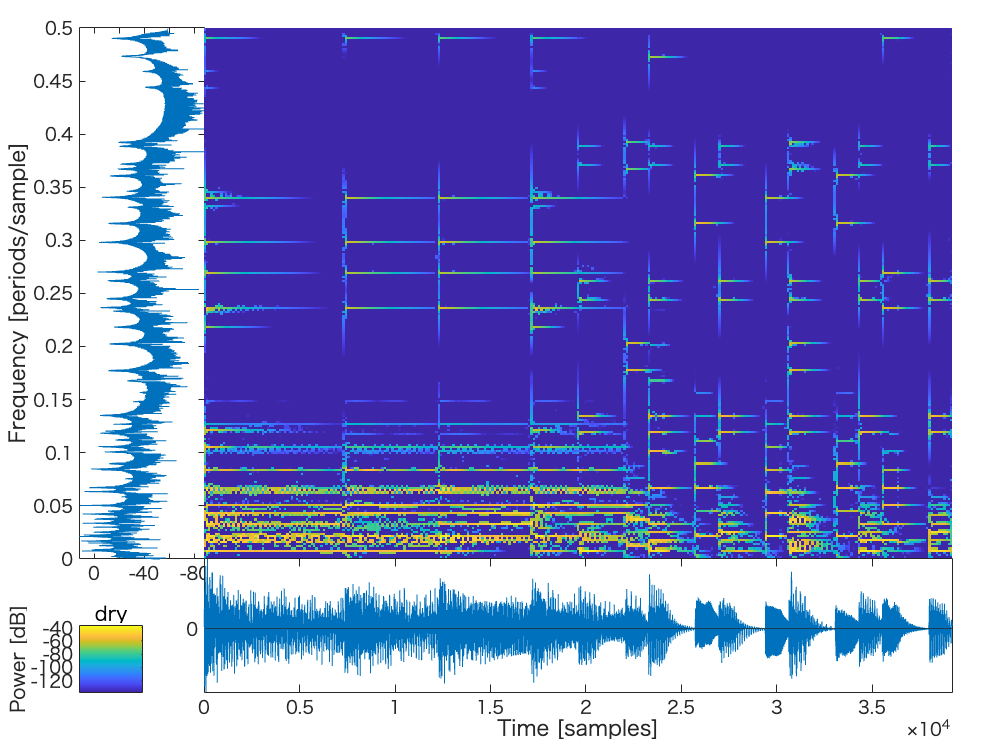


F.plotReassign(ss{1});title("dry"); 
saveas(gcf, "result/" + sprintf(audiofilename,1) + "_dry.png")

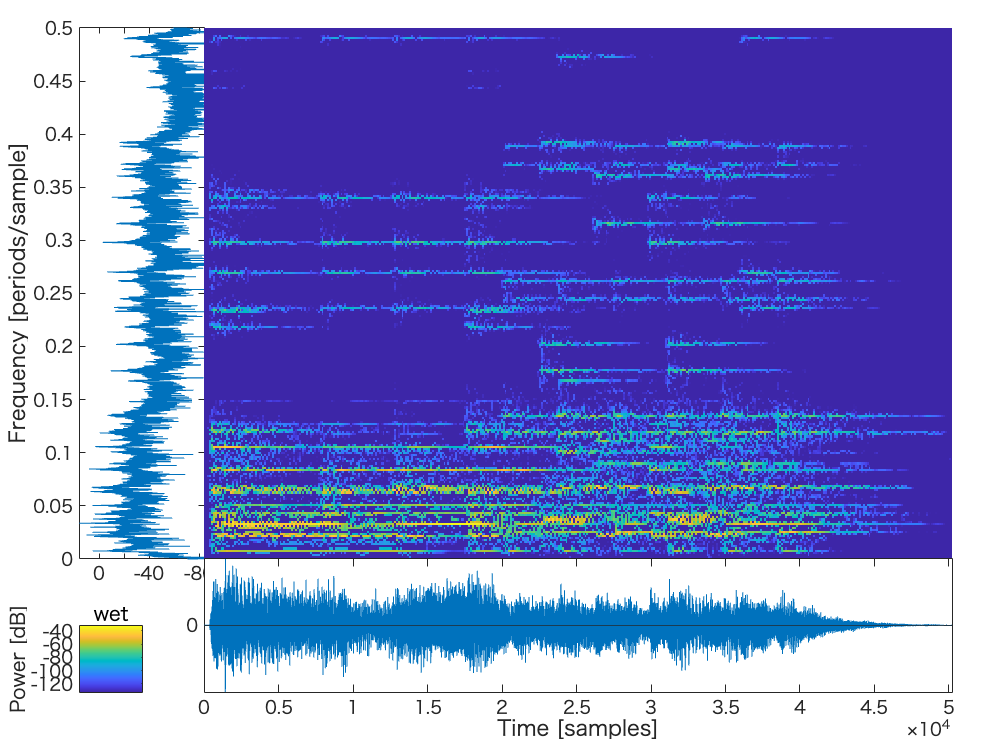

F.plotReassign(obs{1}); title("wet"); 
saveas(gcf, "result/" + sprintf(audiofilename,1) + "_wet.png")

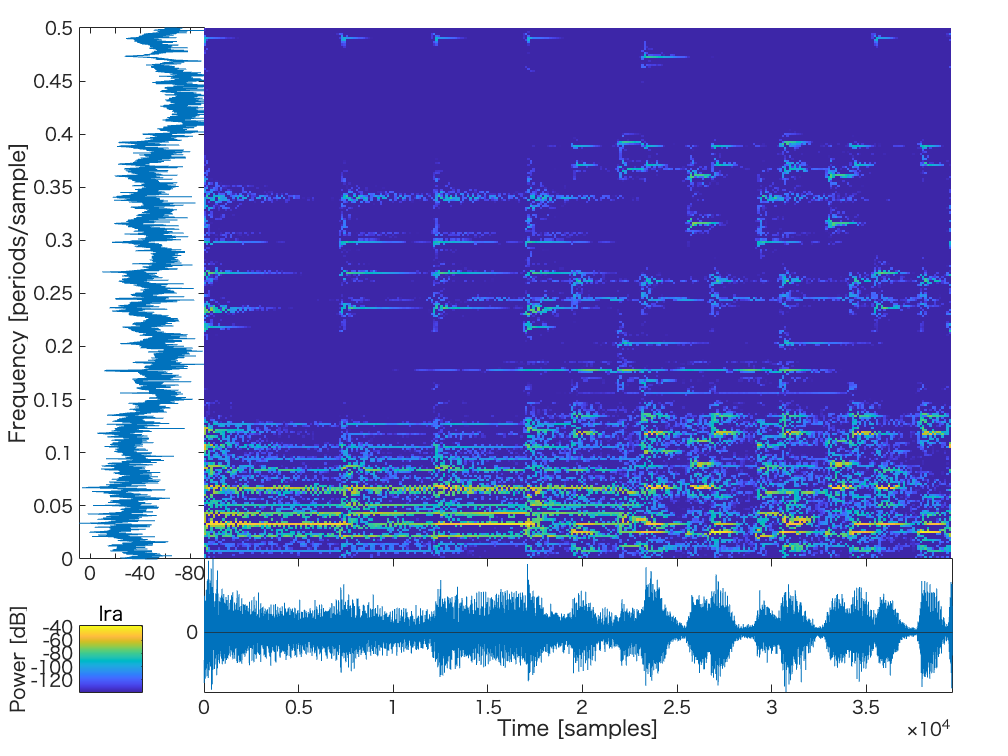

F.plotReassign(ret{1}); title("lra");
saveas(gcf, "result/" + sprintf(audiofilename + "_ORACLE_ret_pad=%d.png",1, padding) )

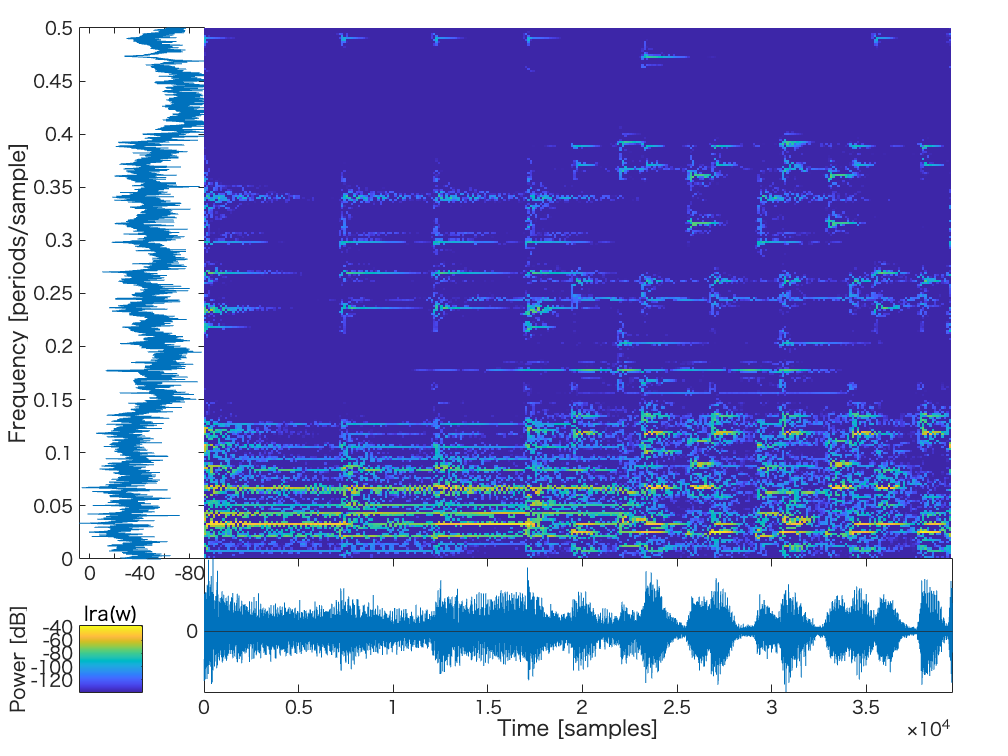

F.plotReassign(ret_w{1}); title("lra(w)");
saveas(gcf, "result/" + sprintf(audiofilename + "_ORACLE(w)_ret.png",1, padding) )

- どの結果も時間のマイナス方向に信号が漏れ出ているのがきになる．

- weight をいれることで若干改善．ただ，きいてもわからない